%load and combine data
LGWVariableName=LGW_CNN.Properties.VariableNames;
AscVariableName=RampAscCNN.Properties.VariableNames;
DscVariableName=Dsc_CNN.Properties.VariableNames;
SitVariableName=Sit_CNN.Properties.VariableNames;
StandVariableName=StandCNN.Properties.VariableNames;

timestamp=[1,11,21,31,41,51,61];
accelerometer=[2:10,12:20,22:30,32:40,42:50,52:60,62:70];

LGWVariableName(accelerometer)=[];
LGW_TimeRemoved=removevars(LGW_CNN,LGWVariableName);

AscVariableName(accelerometer)=[];
Asc_TimeRemoved=removevars(RampAscCNN,AscVariableName);

DscVariableName(accelerometer)=[];
Dsc_TimeRemoved=removevars(Dsc_CNN,DscVariableName);

SitVariableName(accelerometer)=[];
Sit_TimeRemoved=removevars(Sit_CNN,SitVariableName);

StandVariableName(accelerometer)=[];
Stand_TimeRemoved=removevars(StandCNN,StandVariableName);

Data_Table = [LGW_TimeRemoved;Asc_TimeRemoved;Dsc_TimeRemoved;Sit_TimeRemoved;Stand_TimeRemoved];

% Normalize to range [0, 1]
Data_Array = table2array(Data_Table);
Data_Min = min(Data_Array, [], 1); % Minimum of each column
Data_Max = max(Data_Array, [], 1); % Maximum of each column
Data_Array_Normalized = (Data_Array - Data_Min) ./ (Data_Max - Data_Min);

% Replace normalized numeric data back into the table
Data_Input= array2table(Data_Array_Normalized, ...
    'VariableNames', Data_Table.Properties.VariableNames);

%define targets

classes = ["LGW", "Ramp Ascend", "Ramp Descend", "Sit to Stand", "Stand to Sit"];
repetitions = [19187, 9506, 9224, 5915, 5337];
CNN_Targets =  repelem(classes', repetitions');
CNN_Targets = categorical(CNN_Targets);

% Step 2: Group data into trials (before splitting into train, val, and test)
% Make sure the data is grouped into trials and time series is preserved within each trial
[All_Data, All_Targets] = groupIntoTrials(table2cell(Data_Input), CNN_Targets, repetitions, classes);

% Step 3: Split trials into training, validation, and test sets (preserve trial order)
Num_Trials = length(All_Data);  
Trial_Idx = randperm(Num_Trials);  

% Split the trials
Train_Trials = Trial_Idx(1:round(0.7 * Num_Trials));  % 70% for training
Val_Trials = Trial_Idx(round(0.7 * Num_Trials) + 1:round(0.85 * Num_Trials));  % 15% for validation
Test_Trials = Trial_Idx(round(0.85 * Num_Trials) + 1:end);  % 15% for testing

% Group data into training, validation, and test sets
Train_Data_4D = All_Data(Train_Trials);
Train_Targets = All_Targets(Train_Trials);

Val_Data_4D = All_Data(Val_Trials);
Val_Targets = All_Targets(Val_Trials);

Test_Data_4D = All_Data(Test_Trials);
Test_Targets = All_Targets(Test_Trials);

% Step 3a: Extract the target labels from the cell array (if needed)
Train_Targets_Vec = vertcat(Train_Targets{:});

% Step 3b: Convert the target vector to a categorical array
Train_Targets = categorical(Train_Targets_Vec);

% Repeat the same for validation and test targets
Val_Targets_Vec = vertcat(Val_Targets{:});
Val_Targets = categorical(Val_Targets_Vec);

Test_Targets_Vec = vertcat(Test_Targets{:});
Test_Targets = categorical(Test_Targets_Vec);

% Step 4: Pad sequences to have the same length across all trials
Max_TimeSteps = max(cellfun(@(x) size(x, 1), Train_Data_4D));

% Padding function to handle cell arrays
Padded_Data = @(data) padarray(double(data), [Max_TimeSteps - size(data, 1), 0], NaN, 'post');

% Initialize padded data arrays
Padded_Train_Data = cell(1, numel(Train_Data_4D));
Padded_Val_Data = cell(1, numel(Val_Data_4D));      
Padded_Test_Data = cell(1, numel(Test_Data_4D));    

% Loop through each trial and pad the data
for i = 1:numel(Train_Data_4D)
    % Extract the trial data from the cell
    Trial_Data = Train_Data_4D{i};
    
    % Check if the trial data is a table (and convert to array if it is)
    if istable(Trial_Data)
        Trial_Data = table2array(Trial_Data);  
    end
    
    % Check if the trial data is still in cell format
    if iscell(Trial_Data)
        Trial_Data = cell2mat(Trial_Data);  
    end
    
    % Ensure the trial data is numeric (double type)
    Trial_Data = double(Trial_Data);  
    
    % Apply the padding function
    Padded_Train_Data{i} = Padded_Data(Trial_Data);  
end

% Convert padded data into 4D format
Train_Data_4D = cat(4, Padded_Train_Data{:}); 

% Repeat the same for validation and test data
for i = 1:numel(Val_Data_4D)
    Trial_Data = Val_Data_4D{i};
    
    if istable(Trial_Data)
        Trial_Data = table2array(Trial_Data);  
    end
    
    if iscell(Trial_Data)
        Trial_Data = cell2mat(Trial_Data); 
    end
    
    Trial_Data = double(Trial_Data);
    Padded_Val_Data{i} = Padded_Data(Trial_Data);
end
Val_Data_4D = cat(4, Padded_Val_Data{:});

for i = 1:numel(Test_Data_4D)
    Trial_Data = Test_Data_4D{i};
    
    if istable(Trial_Data)
        Trial_Data = table2array(Trial_Data);
    end
    
    if iscell(Trial_Data)
        Trial_Data = cell2mat(Trial_Data);
    end
    
    Trial_Data = double(Trial_Data);
    Padded_Test_Data{i} = Padded_Data(Trial_Data);
end
Test_Data_4D = cat(4, Padded_Test_Data{:}); 

% Step 6: Define and configure CNN layers
layers = [
    sequenceInputLayer(63, 'MinLength', 1) 
    convolution1dLayer(3, 8, 'Padding', 'same')  
    batchNormalizationLayer  
    reluLayer

    % maxPooling1dLayer(2, 'Stride', 1)  
    convolution1dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    % maxPooling1dLayer(2, 'Stride', 1)  % Pooling again
    convolution1dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    % Use a global pooling layer to collapse the sequence length
    globalAveragePooling1dLayer()
    
    fullyConnectedLayer(5)  % Output layer with no. of classes - 5
    softmaxLayer
    classificationLayer
];

% Convert training data into a cell array
Num_Sequences = size(Train_Data_4D, 4); 
Train_Data_Cell = cell(Num_Sequences, 1); 

for i = 1:Num_Sequences
    % Extract each sequence and reshape to [features x timesteps]
    Train_Data_Cell{i} = reshape(Train_Data_4D(1, :, 1, i), [63, 1]); 
end

% Similarly for validation data
Num_Val_Sequences = size(Val_Data_4D, 4);
Val_Data_Cell = cell(Num_Val_Sequences, 1);
for i = 1:Num_Val_Sequences
    Val_Data_Cell{i} = reshape(Val_Data_4D(1, :, 1, i), [63, 1]);
end

% Similarly for test data
Num_Test_Sequences = size(Test_Data_4D, 4);
Test_Data_Cell = cell(Num_Test_Sequences, 1);
for i = 1:Num_Test_Sequences
    Test_Data_Cell{i} = reshape(Test_Data_4D(1, :, 1, i), [63, 1]);
end

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       16.41% |       14.93% |       1.8593 |       1.8898 |          0.0010 |
|       1 |          50 |       00:00:10 |       82.03% |       77.49% |       0.7935 |       0.7951 |          0.0010 |
|       1 |         100 |       00:00:12 |       78.91% |       86.28% |       0.5957 |       0.4711 |          0.0010 |
|       1 |         150 |       00:00:13 |       94.53% |       90.04% |       0.2752 |       0.3315 |          0.0010 |
|       

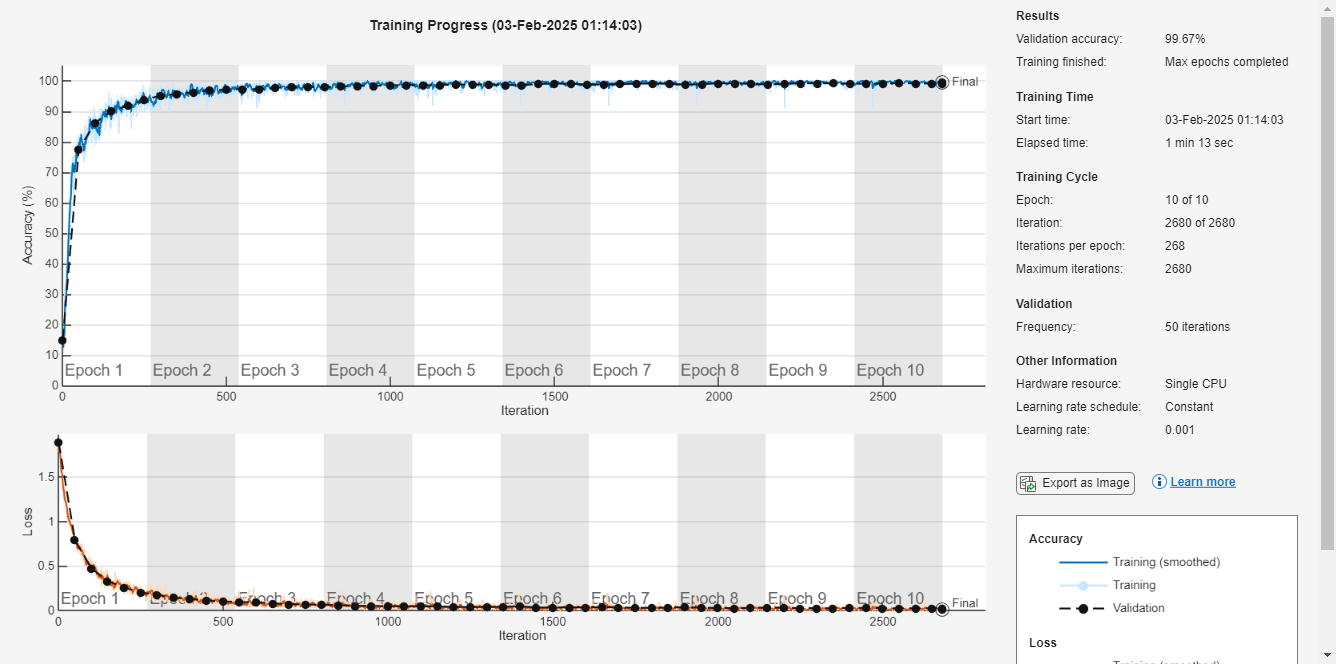

% Step 7: Train the CNN
options = trainingOptions("adam", ...
    "InitialLearnRate", 0.001, ...
    "MaxEpochs", 10, ...
    "ValidationData", {Val_Data_Cell, Val_Targets}, ...
    "Plots", "training-progress");

net = trainNetwork(Train_Data_Cell, Train_Targets, layers, options);

% Step 8: test the model
predictions = classify(net, Test_Data_Cell);
accuracy = sum(predictions == Test_Targets) / numel(Test_Data_Cell);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 99.70%



% Step 9: display confusion matrix
confusionchart(Test_Targets, predictions);
title('Confusion Matrix')

function [groupedData, groupedTargets] = groupIntoTrials(dataRaw, targetRaw, repetitions, classes)
    groupedData = {};
    groupedTargets = {};
    
    trialStart = 1;  
    trialEnd = 0;    
    
    % Iterate over the activities (classes)
    for i = 1:numel(classes)
        numTrials = repetitions(i);  
        
        % For each trial, extract the corresponding data and target label
        for trialIdx = 1:numTrials
            trialEnd = trialStart + size(dataRaw{trialStart}, 1) - 1;  
            trialData = dataRaw(trialStart:trialEnd, :);  
            
            % Add the trial data and its corresponding target class to the output
            groupedData{end + 1} = trialData;  
            groupedTargets{end + 1} = targetRaw(trialStart:trialEnd, :);  
            
            trialStart = trialEnd + 1;  
        end
    end
end

% Discarded Code - due to errors or optimisation

% Data squeeze tried to equalise dimensions of data going to CNN algorithm,
% but erroneous
% Train_Data_Permuted = squeeze(Train_Data_Permuted);
% Val_Data_Permuted = squeeze(Val_Data_Permuted);
% Test_Data_Permuted = squeeze(Test_Data_Permuted);

% Data Normalization after Padding. Removed due to redundancy
% % Step 5: Normalize to range [0, 1]
% Train_Data_Normalized = (4D_Train_Data - min(trainData4D(:))) / (max(4D_Train_Data(:)) - min(4D_Train_Data(:)));
% Val_Data_Normalized = (valData4D - min(4D_Val_Data(:))) / (max(4D_Val_Data(:)) - min(4D_Val_Data(:)));
% Test_Data_Normalized = (4D_Test_Data - min(4D_Test_Data(:))) / (max(4D_Test_Data(:)) - min(4D_Test_Data(:)));